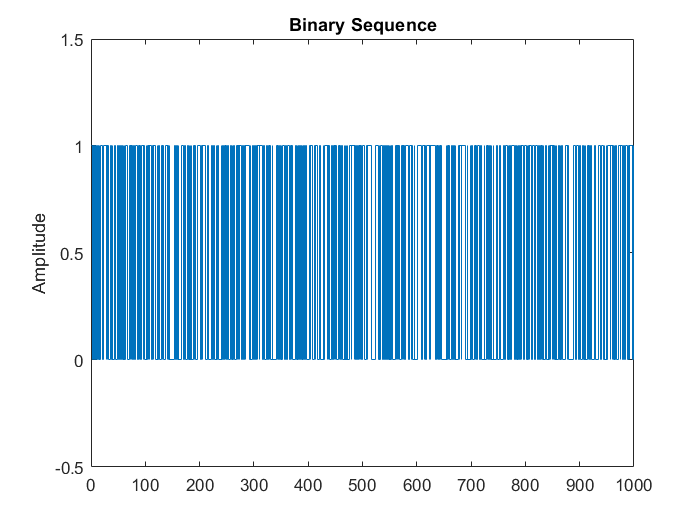

%%%%%%%%%% To run a particular section, comment other sections %%%%%%%%




%%%%%%%%%%%%%%%%%%% Question 01 - Question 04 %%%%%%%%%%%%%%%%%%%%%


L=1000;         %length of the binary sequence
binarySequence = rand(1,L)>0.5;  %generating the binary sequence 
stairs(binarySequence);      %plotting the binary sequence
title("Binary Sequence");
ylabel("Amplitude");
ylim([-0.5,1.5]);

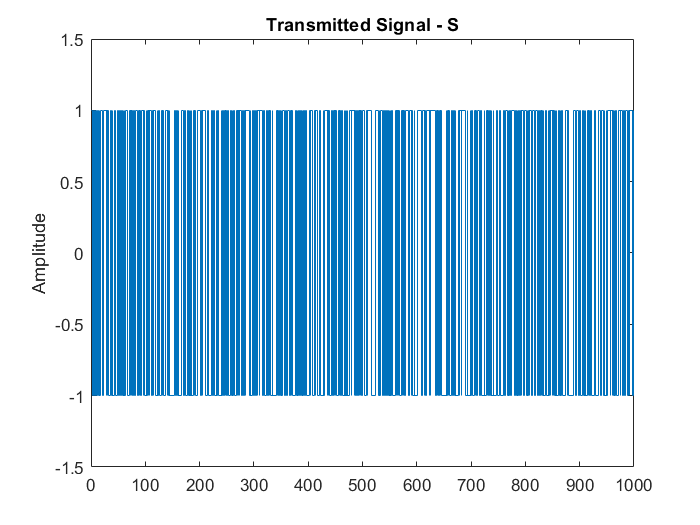


A=1;       %amplitude of the transmitting sequence
S= 2*1*binarySequence-A;   %generating the stream of rectangular pulse with the amplitude of A and -A
stairs(S);         %plotting the transmitting signal
title("Transmitted Signal - S");
ylabel("Amplitude");
ylim([-0.5-A,A+0.5]);

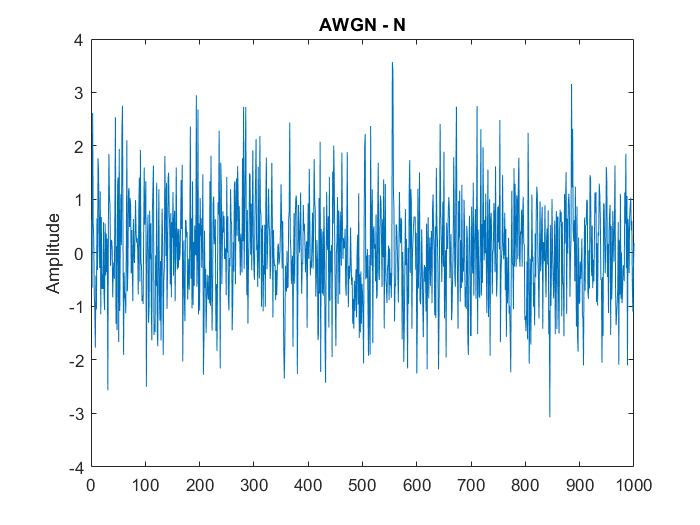



N= normrnd(0,1,1,L);   %generating the AWGN with the mean=0 and the variance=1
plot(N);         %plotting the AWGN signal
title("AWGN - N");
ylabel("Amplitude");

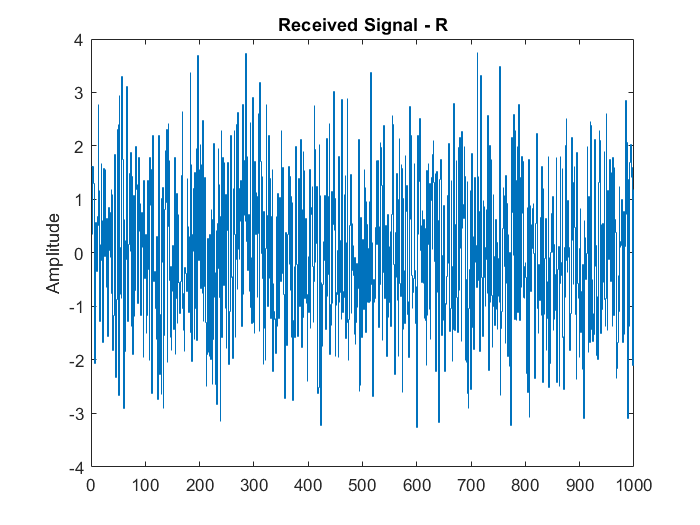



R=S+N;      %generating the received signal
stairs(R);    %plotting the received signal   
title("Received Signal - R");
ylabel("Amplitude");

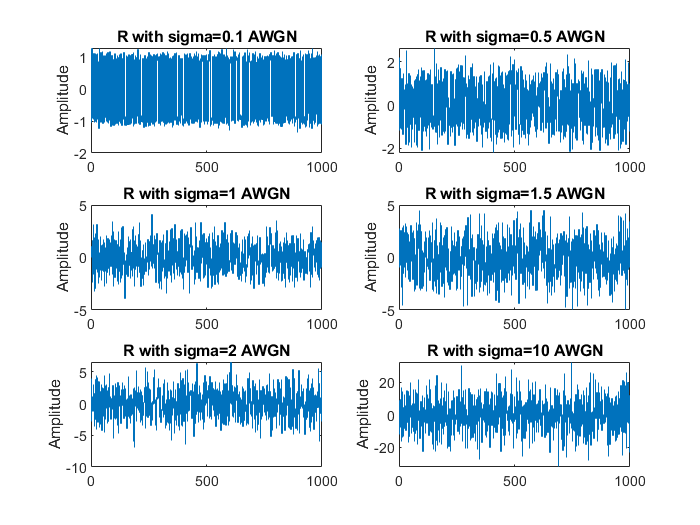



%effect of the variance of the AWGN signal on the received signal

%generating AWGN signals with different varinces
N1= normrnd(0,0.1,1,L); 
N2= normrnd(0,0.5,1,L); 
N3= normrnd(0,1,1,L);
N4= normrnd(0,1.5,1,L); 
N5= normrnd(0,2,1,L); 
N6= normrnd(0,10,1,L);
%generating the corresponding received signal 
R1=S+N1;
R2=S+N2;
R3=S+N3;
R4=S+N4;
R5=S+N5;
R6=S+N6;
%plotting received signal
subplot(3,2,1);
stairs(R1);
title("R with sigma=0.1 AWGN");
ylabel("Amplitude");
subplot(3,2,2);
stairs(R2);
title("R with sigma=0.5 AWGN");
ylabel("Amplitude");
subplot(3,2,3);
stairs(R3);
title("R with sigma=1 AWGN");
ylabel("Amplitude");
subplot(3,2,4);
stairs(R4);
title("R with sigma=1.5 AWGN");
ylabel("Amplitude");
subplot(3,2,5);
stairs(R5);
title("R with sigma=2 AWGN");
ylabel("Amplitude");
subplot(3,2,6);
stairs(R6);
title("R with sigma=10 AWGN");
ylabel("Amplitude");

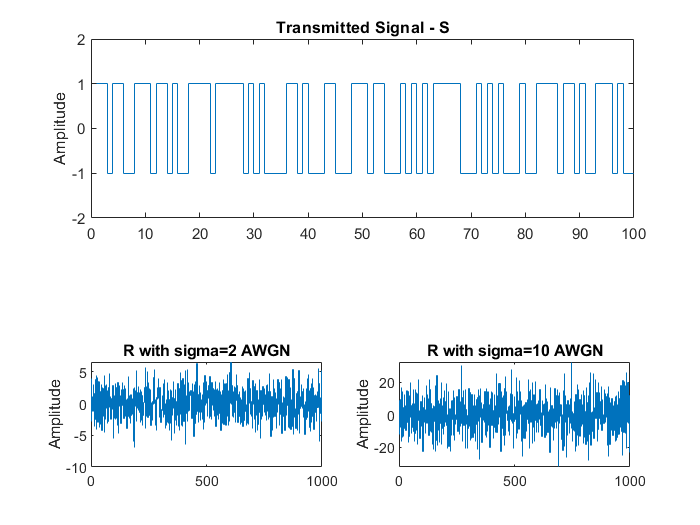



%decoding the received signal

tau= 0;    %threshold value
Y= 2*A*(R>tau)-A;   %mapping Y>0 samples to 'A' and Y<0 samples to '-A'
subplot(2,1,1);
stairs(S);       %plotting the transmitted signal
title("Transmitted Signal - S");
ylabel("Amplitude");
ylim([-1-A,A+1]);
xlim([0,100]);

subplot(2,1,2);
stairs(Y);      %ploting the received signal
title("Decoded Signal - Y");
ylabel("Amplitude");
ylim([-1-A,A+1]);
xlim([0,100]);


%comparing the transmitted signal and the received signal

%decoding the received signal with different variances
Y1= 2*A*(R1>tau)-A;
Y2= 2*A*(R2>tau)-A;
Y3= 2*A*(R3>tau)-A;
Y4= 2*A*(R4>tau)-A;
Y5= 2*A*(R5>tau)-A;
Y6= 2*A*(R6>tau)-A;
%calculating the number of error bits in each decoded signal
No_of_error_bits_of_Y1= sum(abs(S-Y1)>0);
No_of_error_bits_of_Y2= sum(abs(S-Y2)>0);
No_of_error_bits_of_Y3= sum(abs(S-Y3)>0);
No_of_error_bits_of_Y4= sum(abs(S-Y4)>0);
No_of_error_bits_of_Y5= sum(abs(S-Y5)>0);
No_of_error_bits_of_Y6= sum(abs(S-Y6)>0);
%calculating the error rate of each decoded signal
Error_rate_of_Y1= No_of_error_bits_of_Y1*100/L;
Error_rate_of_Y2= No_of_error_bits_of_Y2*100/L;
Error_rate_of_Y3= No_of_error_bits_of_Y3*100/L;
Error_rate_of_Y4= No_of_error_bits_of_Y4*100/L;
Error_rate_of_Y5= No_of_error_bits_of_Y5*100/L;
Error_rate_of_Y6= No_of_error_bits_of_Y6*100/L;
%displaing the error rate
disp("Error rate for sigma=0.1 : "+Error_rate_of_Y1);

Error rate for sigma=0.1 : 0


disp("Error rate for sigma=0.5 : "+Error_rate_of_Y2);

Error rate for sigma=0.5 : 2.4


disp("Error rate for sigma=1   : "+Error_rate_of_Y3);

Error rate for sigma=1   : 15.9


disp("Error rate for sigma=1.5 : "+Error_rate_of_Y4);

Error rate for sigma=1.5 : 24.4


disp("Error rate for sigma=2   : "+Error_rate_of_Y5);

Error rate for sigma=2   : 29.8


disp("Error rate for sigma=10  : "+Error_rate_of_Y6);

Error rate for sigma=10  : 45.9


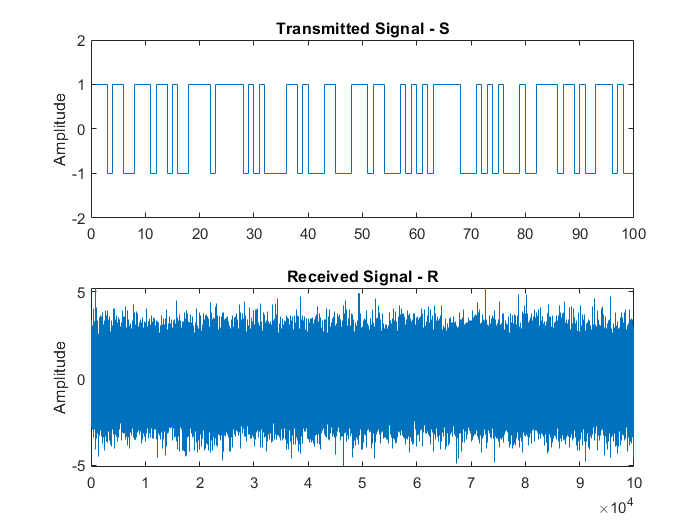






%%%%%%%%%%%%%%%%%%%%%%% QUESTION 05 - QUESTION 07 %%%%%%%%%%%%%%%%%%%%%%%%%


L=100000;     %length of the binary sequence
binarySequence = rand(1,L)>0.5;   %generating the binary sequence 
stairs(binarySequence);      %plotting the binary sequence
title("Binary Sequence");
ylabel("Amplitude");
ylim([-0.5,1.5]);

A=1;    %amplitude of the transmitting signal
S= 2*A*binarySequence-A;   %generating the stream of rectangular pulse with the amplitude of 1 and -1
stairs(S);     %plotting the transmitted signal
title("Transmitted Signal - S");
ylabel("Amplitude");
ylim([-0.5-A,A+0.5]);


N= normrnd(0,1,1,L); %generating the AWGN with the mean=0 and the variance=1
plot(N);        %plotting the AWGN signal
title("AWGN - N");
ylabel("Amplitude");


R=S+N;    %generating the received signal
stairs(R);    %plotting the received signal 
title("Received Signal - R");
ylabel("Amplitude");

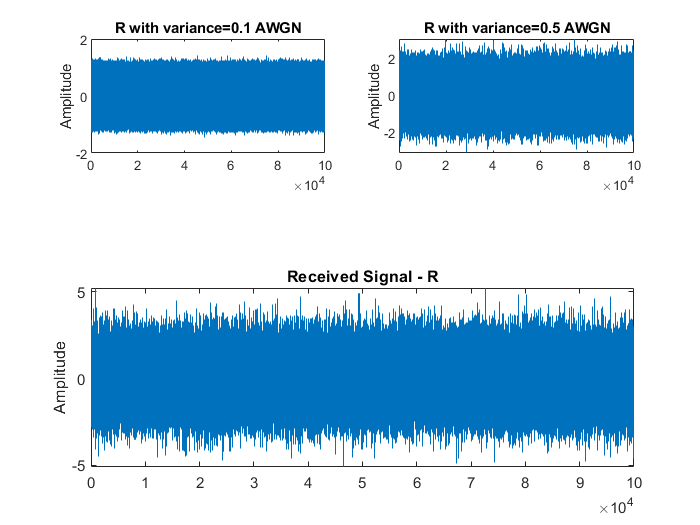




%effect of the variance of the AWGN signal on the received signal

%generating AWGN signals with different varinces
N1= normrnd(0,0.1,1,L); 
N2= normrnd(0,0.5,1,L); 
N3= normrnd(0,1,1,L);
N4= normrnd(0,1.5,1,L); 
N5= normrnd(0,2,1,L); 
N6= normrnd(0,10,1,L);
%generating the corresponding received signal 
R1=S+N1;
R2=S+N2;
R3=S+N3;
R4=S+N4;
R5=S+N5;
R6=S+N6;
%plotting received signal
subplot(3,2,1);
stairs(R1);
title("R with variance=0.1 AWGN");
ylabel("Amplitude");
subplot(3,2,2);
stairs(R2);
title("R with variance=0.5 AWGN");
ylabel("Amplitude");

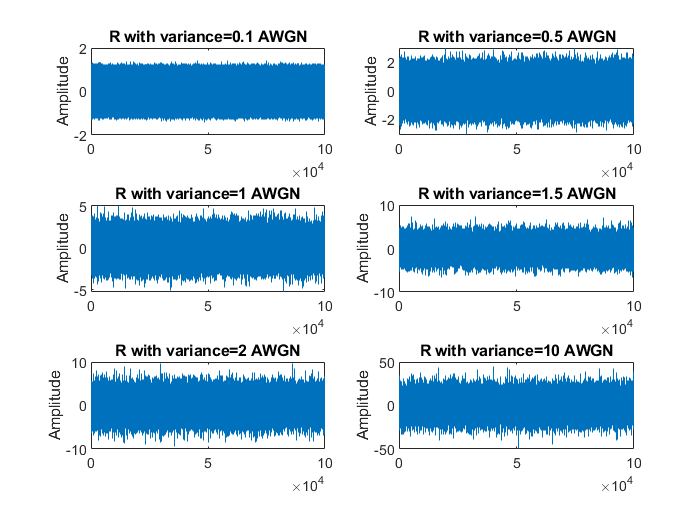

subplot(3,2,3);
stairs(R3);
title("R with variance=1 AWGN");
ylabel("Amplitude");
subplot(3,2,4);
stairs(R4);
title("R with variance=1.5 AWGN");
ylabel("Amplitude");
subplot(3,2,5);
stairs(R5);
title("R with variance=2 AWGN");
ylabel("Amplitude");
subplot(3,2,6);
stairs(R6);
title("R with variance=10 AWGN");
ylabel("Amplitude");

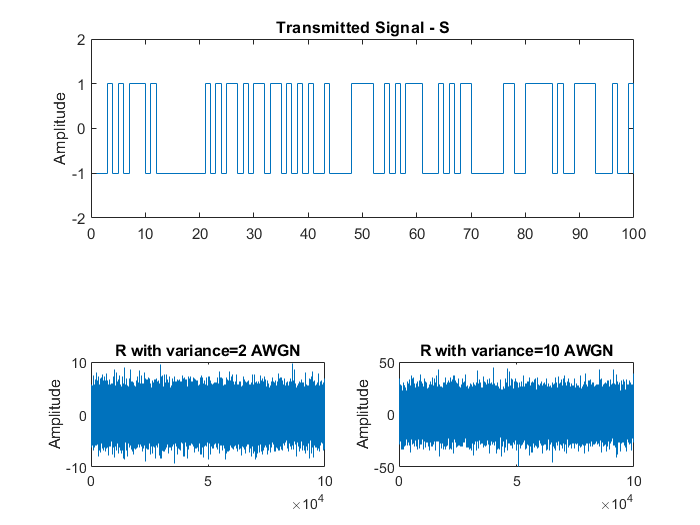



%decoding the received signal

tau= 0;     %threshold value
Y= 2*A*(R>tau)-A;    %mapping Y>0 samples to 'A' and Y<0 samples to '-A'
subplot(2,1,1);
stairs(S);         %plotting the transmitted signal
title("Transmitted Signal - S");
ylabel("Amplitude");
ylim([-1-A,A+1]);
xlim([0,100]);

subplot(2,1,2);
stairs(Y);          %plotting the received signal
title("Decoded Signal - Y");
ylabel("Amplitude");
ylim([-1-A,A+1]);
xlim([0,100]);



%comparing the transmitted signal and the received signal

%decoding the received signal with different variances
Y1= 2*A*(R1>tau)-A;
Y2= 2*A*(R2>tau)-A;
Y3= 2*A*(R3>tau)-A;
Y4= 2*A*(R4>tau)-A;
Y5= 2*A*(R5>tau)-A;
Y6= 2*A*(R6>tau)-A;
%calculating the number of error bits in each decoded signal
No_of_error_bits_of_Y1= sum(abs(S-Y1)>0);
No_of_error_bits_of_Y2= sum(abs(S-Y2)>0);
No_of_error_bits_of_Y3= sum(abs(S-Y3)>0);
No_of_error_bits_of_Y4= sum(abs(S-Y4)>0);
No_of_error_bits_of_Y5= sum(abs(S-Y5)>0);
No_of_error_bits_of_Y6= sum(abs(S-Y6)>0);
%calculating the error rate of each decoded signal
Error_rate_of_Y1= No_of_error_bits_of_Y1*100/L;
Error_rate_of_Y2= No_of_error_bits_of_Y2*100/L;
Error_rate_of_Y3= No_of_error_bits_of_Y3*100/L;
Error_rate_of_Y4= No_of_error_bits_of_Y4*100/L;
Error_rate_of_Y5= No_of_error_bits_of_Y5*100/L;
Error_rate_of_Y6= No_of_error_bits_of_Y6*100/L;
%displaing the error rate
disp("Error rate for sigma=0.1 : "+Error_rate_of_Y1);

Error rate for sigma=0.1 : 0


disp("Error rate for sigma=0.5 : "+Error_rate_of_Y2);

Error rate for sigma=0.5 : 2.293


disp("Error rate for sigma=1   : "+Error_rate_of_Y3);

Error rate for sigma=1   : 15.977


disp("Error rate for sigma=1.5 : "+Error_rate_of_Y4);

Error rate for sigma=1.5 : 25.203


disp("Error rate for sigma=2   : "+Error_rate_of_Y5);

Error rate for sigma=2   : 30.933


disp("Error rate for sigma=10  : "+Error_rate_of_Y6);

Error rate for sigma=10  : 46.324


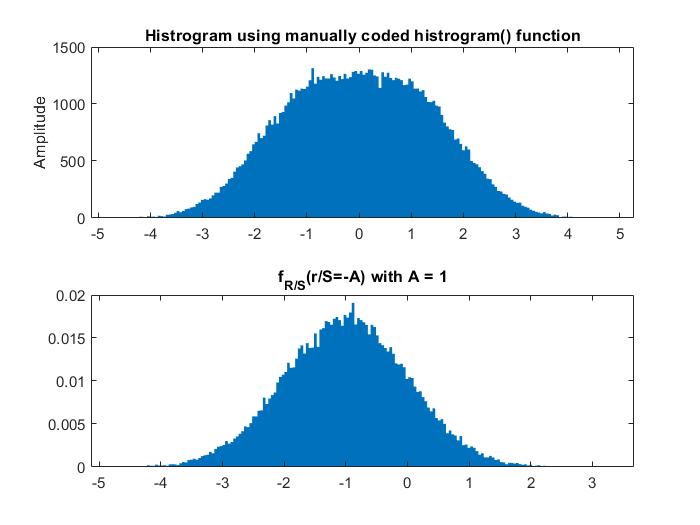



%HISTOGRAM


numberOfBins=200;    %number of bins of the histogram
histrogramarrayR= histrogram(R,numberOfBins);
subplot(2,1,1);
bar(histrogramarrayR(1,:),histrogramarrayR(2,:),1);   %ploting the histrogram manually
title("Histrogram using manually coded histrogram() function");
ylabel("Amplitude");
subplot(2,1,2);
hist(R,numberOfBins);    %plotting the histtogram using hist() function
title("Histrogram using hist() buil-in function");
ylabel("Amplitude");


%Conditional PDF when S=A

ZeroArray=zeros(1,L);    %creating a zero array with the length of the binary sequence
for i = 1:L
   if S(i) == A    %checking wether the transmitted bit is eqaul to 'A' or not
      ZeroArray(i)=R(i);  %if the transmitted bit is equal to 'A', then it is added to the ZeroArray
   end
end
totNonZeroVal= sum(abs(ZeroArray)>0); %calculating the number of non zero bits in the ZeroArray
R_A= zeros(1,totNonZeroVal);    %creating an array with the length of totNonZeroVal
k=1;
for j =1:L        %adding non zero bits of the ZeroArray to R_A
    if ZeroArray(j)~=0
        R_A(k)=ZeroArray(j);
        k=k+1;
   end
end 
histrogramArrayR_A= histrogram(R_A,numberOfBins);
normHistrogramArrayR_A= histrogramArrayR_A./[1;length(R_A)];   %normalized the histogram
bar(normHistrogramArrayR_A(1,:),normHistrogramArrayR_A(2,:),1);  %plotting the normalized histogram
title("f_{R/S}(r/S=A) with A = "+ A);


%Conditional PDF when S=-A

ZeroArray=zeros(1,L);   %creating a zero array with the length of the binary sequence
for i = 1:L
    if S(i) == -A    %checking wether the transmitted bit is eqaul to '-A' or not
        ZeroArray(i)=R(i);    %if the transmitted bit is equal to '-A', then it is added to the ZeroArray
    end
end
totNonZeroVal= sum(abs(ZeroArray)>0);    %calculating the number of non zero bits in the ZeroArray
R_A= zeros(1,totNonZeroVal);        %creating an array with the length of totNonZeroVal
k=1;
for j =1:L      %adding non zero bits of the ZeroArray to R_A
    if ZeroArray(j)~=0
        R_A(k)=ZeroArray(j);
        k=k+1;
    end
end
histrogramArrayR_A= histrogram(R_A,numberOfBins);
normHistrogramArrayR_A= histrogramArrayR_A./[1;length(R_A)];    %normalized the histogram
bar(normHistrogramArrayR_A(1,:),normHistrogramArrayR_A(2,:),1);      %plotting the normalized histogram
title("f_{R/S}(r/S=-A) with A = "+ A);



%Comparison changing A

A=[-0.1,0.1];
for m=1:length(A)
S= 2*abs(A(m))*binarySequence-abs(A(m));
R=S+N;
ZeroArray=zeros(1,L);
for i = 1:L
    if S(i) == A(m)
        ZeroArray(i)=R(i);
    end
end
totNonZeroVal= sum(abs(ZeroArray)>0);
R_A= zeros(1,totNonZeroVal);
k=1;
for j =1:L
    if ZeroArray(j)~=0
        R_A(k)=ZeroArray(j);
        k=k+1;
    end
end
histrogramArrayR_A= histrogram(R_A,numberOfBins);
normHistrogramArrayR_A= histrogramArrayR_A./[1;length(R_A)];
subplot(1,2,m);
bar(normHistrogramArrayR_A(1,:),normHistrogramArrayR_A(2,:),1);
title("f_{R/S}(r/S="+A(m)+") with A = "+ abs(A(m)));

end


%Expected Value

A=[-0.1,0.1,-0.5,0.5,-1,1,-5,5,-10,10];
for m=1:length(A)
S= 2*abs(A(m))*binarySequence-abs(A(m));
R=S+N;
ZeroArray=zeros(1,L);
for i = 1:L
   if S(i) == A(m)
      ZeroArray(i)=R(i);
   end
end
totNonZeroVal= sum(abs(ZeroArray)>0);
R_A= zeros(1,totNonZeroVal);
k=1;
for j =1:L
    if ZeroArray(j)~=0
        R_A(k)=ZeroArray(j);
        k=k+1;
    end
end
ExpectedValueOfR= mean(R);    %taking the mean value of the received bit array
ExpectedValueOfR_A= mean(R_A);
disp("E[R] = "+ExpectedValueOfR);
disp("E[R/S="+A(m)+"] = "+ExpectedValueOfR_A);
end

E[R] = -0.0011427


E[R/S=-0.1] = -0.099394


E[R] = -0.0011427


E[R/S=0.1] = 0.097054


E[R] = -0.0010307


E[R/S=-0.5] = -0.49939


E[R] = -0.0010307


E[R/S=0.5] = 0.49705


E[R] = -0.00089068


E[R/S=-1] = -0.99939


E[R] = -0.00089068


E[R/S=1] = 0.99705


E[R] = 0.00022932


E[R/S=-5] = -4.9994


E[R] = 0.00022932


E[R/S=5] = 4.9971


E[R] = 0.0016293


E[R/S=-10] = -9.9994


E[R] = 0.0016293


E[R/S=10] = 9.9971




%PDF of R

A=10;  
S= 2*A*binarySequence-A;
R=S+N;
histrogramArrayPDF_R=histrogram(R,numberOfBins);
pdfArray= histrogramArrayPDF_R./[1;length(R)];
bar(pdfArray(1,:),pdfArray(2,:),1);
title("f_{R}(r) with A = "+A);







%%%%%%%%%%%%%%%%%%%%%%%% QUESTION 6 %%%%%%%%%%%%%%%%%%%%%%%%%%%


I=normrnd(0,1,1,L);    %generating the inteference signal
R=S+N+I;      %generating the received signal
 


%Conditional PDF when S=A

ZeroArray=zeros(1,L);
for i = 1:L
    if S(i) == A
       ZeroArray(i)=R(i);
    end
end
totNonZeroVal= sum(abs(ZeroArray)>0);
R_A= zeros(1,totNonZeroVal);
k=1;
for j =1:L
    if ZeroArray(j)~=0
       R_A(k)=ZeroArray(j);
      k=k+1;
    end
end 
histrogramArrayR_A= histrogram(R_A,numberOfBins);
normHistrogramArrayR_A= histrogramArrayR_A./[1;length(R_A)];
bar(normHistrogramArrayR_A(1,:),normHistrogramArrayR_A(2,:),1);
title("f_{R/S}(r/S=A) with A = "+ A);



%Conditional PDF when S=-A

ZeroArray=zeros(1,L);
for i = 1:L
   if S(i) == -A
       ZeroArray(i)=R(i);
   end
end
totNonZeroVal= sum(abs(ZeroArray)>0);
R_A= zeros(1,totNonZeroVal);
k=1;
for j =1:L
    if ZeroArray(j)~=0
        R_A(k)=ZeroArray(j);
        k=k+1;
   end
end
histrogramArrayR_A= histrogram(R_A,numberOfBins);
normHistrogramArrayR_A= histrogramArrayR_A./[1;length(R_A)];
bar(normHistrogramArrayR_A(1,:),normHistrogramArrayR_A(2,:),1);
title("f_{R/S}(r/S=-A) with A = "+ A);


%Comparison changing A

A=[-10,10];
for m=1:length(A)
S= 2*abs(A(m))*binarySequence-abs(A(m));
R=S+N+I;
ZeroArray=zeros(1,L);
for i = 1:L
    if S(i) == A(m)
        ZeroArray(i)=R(i);
    end
end
totNonZeroVal= sum(abs(ZeroArray)>0);
R_A= zeros(1,totNonZeroVal);
k=1;
for j =1:L
    if ZeroArray(j)~=0
        R_A(k)=ZeroArray(j);
        k=k+1;
    end
end
histrogramArrayR_A= histrogram(R_A,numberOfBins);
normHistrogramArrayR_A= histrogramArrayR_A./[1;length(R_A)];
subplot(1,2,m);
bar(normHistrogramArrayR_A(1,:),normHistrogramArrayR_A(2,:),1);
title("f_{R/S}(r/S="+A(m)+") with A = "+ abs(A(m)));

end



%Expected Value

A=[-0.1,0.1,-0.5,0.5,-1,1,-5,5,-10,10];
for m=1:length(A)
S= 2*abs(A(m))*binarySequence-abs(A(m));
R=S+N+I;
ZeroArray=zeros(1,L);
for i = 1:L
   if S(i) == A(m)
      ZeroArray(i)=R(i);
   end
end
totNonZeroVal= sum(abs(ZeroArray)>0);
R_A= zeros(1,totNonZeroVal);
k=1;
for j =1:L
    if ZeroArray(j)~=0
        R_A(k)=ZeroArray(j);
        k=k+1;
    end
end
ExpectedValueOfR= mean(R);
ExpectedValueOfR_A= mean(R_A);
disp("E[R] = "+ExpectedValueOfR);
disp("E[R/S="+A(m)+"] = "+ExpectedValueOfR_A);
end

E[R] = 0.0024695


E[R/S=-0.1] = -0.09067


E[R] = 0.0024695


E[R/S=0.1] = 0.095557


E[R] = 0.0025815


E[R/S=-0.5] = -0.49067


E[R] = 0.0025815


E[R/S=0.5] = 0.49556


E[R] = 0.0027215


E[R/S=-1] = -0.99067


E[R] = 0.0027215


E[R/S=1] = 0.99556


E[R] = 0.0038415


E[R/S=-5] = -4.9907


E[R] = 0.0038415


E[R/S=5] = 4.9956


E[R] = 0.0052415


E[R/S=-10] = -9.9907


E[R] = 0.0052415


E[R/S=10] = 9.9956




%PDF of R

A=10;
S= 2*A*binarySequence-A;
R=S+N+I;
histrogramArrayPDF_R=histrogram(R,numberOfBins);
pdfArray= histrogramArrayPDF_R./[1;length(R)];
bar(pdfArray(1,:),pdfArray(2,:),1);
title("f_{R}(r) with A = "+A);





%%%%%%%%%%%%%%%%%%%%%%%%%%% QUESTION 07 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


Alpha = 2;
R = Alpha*S + N;     %generating the received signal
numberOfBins=200;



%Conditional PDF when S=A

ZeroArray=zeros(1,L);
for i = 1:L
  if S(i) == -A
     ZeroArray(i)=R(i);
  end
end
totNonZeroVal= sum(abs(ZeroArray)>0);
R_A= zeros(1,totNonZeroVal);
k=1;
for j =1:L
    if ZeroArray(j)~=0
       R_A(k)=ZeroArray(j);
      k=k+1;
    end
end 
histrogramArrayR_A= histrogram(R_A,numberOfBins);
normHistrogramArrayR_A= histrogramArrayR_A./[1;length(R_A)];
bar(normHistrogramArrayR_A(1,:),normHistrogramArrayR_A(2,:),1);
title("f_{R/S}(r/S=-A) with A = "+ A);
 



%Expected Value

A=[-1,1];
for m=1:length(A)
S= 2*abs(A(m))*binarySequence-abs(A(m));
R = Alpha*S + N;
ZeroArray=zeros(1,L);
for i = 1:L
   if S(i) == A(m)
      ZeroArray(i)=R(i);
   end
end
totNonZeroVal= sum(abs(ZeroArray)>0);
R_A= zeros(1,totNonZeroVal);
k=1;
for j =1:L
    if ZeroArray(j)~=0
         R_A(k)=ZeroArray(j);
       k=k+1;
   end
end
ExpectedValueOfR= mean(R);
ExpectedValueOfR_A= mean(R_A);
disp("E[R] = "+ExpectedValueOfR+ "  Alpha = "+Alpha);
disp("E[R/S="+A(m)+"] = "+ExpectedValueOfR_A+ "  Alpha = "+Alpha);
end

E[R] = -0.00061068  Alpha = 2


E[R/S=-1] = -1.9994  Alpha = 2


E[R] = -0.00061068  Alpha = 2


E[R/S=1] = 1.9971  Alpha = 2


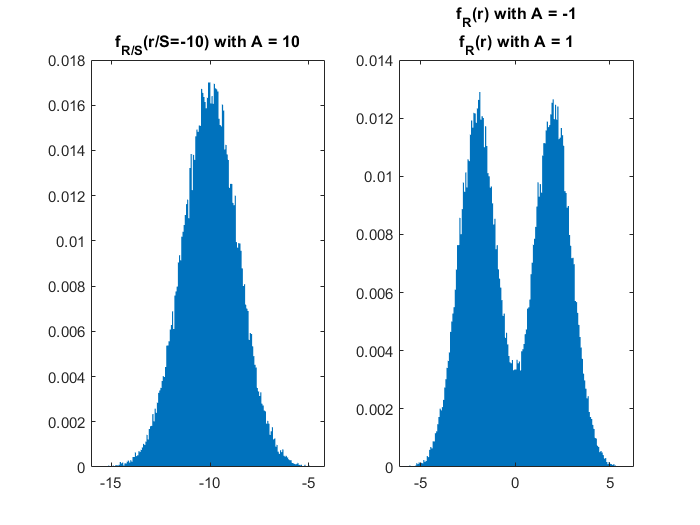




%PDF of R

histrogramArrayPDF_R=histrogram(R,numberOfBins);
pdfArray= histrogramArrayPDF_R./[1;length(R)];
bar(pdfArray(1,:),pdfArray(2,:),1);
title("f_{R}(r) with A = "+A);

%%%%%%%%%%%%% Manually coded histogram function %%%%%%%%%%%%%%%%%%%

function histrogramArray = histrogram(signal,numberOfBins)
    maxValue= max(signal);  %taking the maximum value of the signal
    minValue=min(signal);    %taking the minimum value of the signal
    
    binWidth= (maxValue-minValue)/numberOfBins;    %calculating the width of a bin
    
    histrogramArray= zeros(2,numberOfBins);
    
    histrogramArray(1,:) = [minValue+binWidth/2:binWidth:maxValue];
    
    for i = 1:numberOfBins
        histrogramArray(2,i) = sum((signal>=(minValue+binWidth*(i-1))) & (signal<(minValue+binWidth*i)));
    end
    
end

